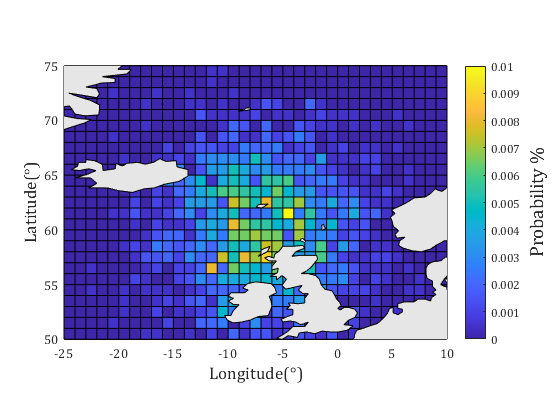

clc;clear;clf
% 创建地图区域
ax=axesm('MapProjection','mercator');
ax.XLim=[-25,10];
ax.YLim=[50,75];
ax.XTick=-25:5:10;
ax.YTick=50:5:75;

% 生成随机分布
N=2000;
lon=randn(1,N)*5-7;
lat=randn(1,N)*5+60;
lonEdge=-25:10;
latEdge=50:75;
%  计算每个格子概率，且总和为一
cnt=histcounts2(lon,lat,lonEdge,latEdge,'Normalization','probability')';  
[lonEdge,latEdge]=meshgrid(lonEdge,latEdge);

% 绘制岸线及密度分布
load coastlines
mapshow(ax,lonEdge,latEdge,cnt,'DisplayType','texturemap','EdgeColor','k')
mapshow(ax,coastlon,coastlat,'DisplayType','polygon','FaceColor',[230,230,230]./255)

% 绘制colorbar并修饰
cbar=colorbar;
cbar.Label.String='Probability %';
cbar.Label.FontName='Cambria';
cbar.Label.FontSize=14;

% XLabel,YLabel
ax.FontName='Cambria';
ax.XLabel.String='Longitude(°)';
ax.XLabel.FontSize=13;
%
ax.YLabel.String='Latitude(°)';
ax.YLabel.FontSize=13;